% Obtain the time-domain features for the second utterance recorded
% in question 2

% Short time analysis code
clear all
close all
clc

% recording audio 
fs = 16000;
NumSeconds = 5;
NumBits_quant = 16;
Num_channels = 1; % mono 1 channel, 2 for stereo

[speech_second, fs] = audioread('abhishek_second.wav');
speech = speech_second;

WL = 25;
WS = 10;

WL_samp = round(WL*0.001*fs);
WS_Samp = round(WS*0.001*fs);
[STEn, STMag] = STEn_STM_calc(speech, WL_samp, WS_Samp, fs);
STEn = STEn/max(STEn);
STMag = STMag/max(STMag);
t= 0:(1/fs):(length(speech)-1)/fs;
figure('rend','painters','pos',[10 10 900 600]);

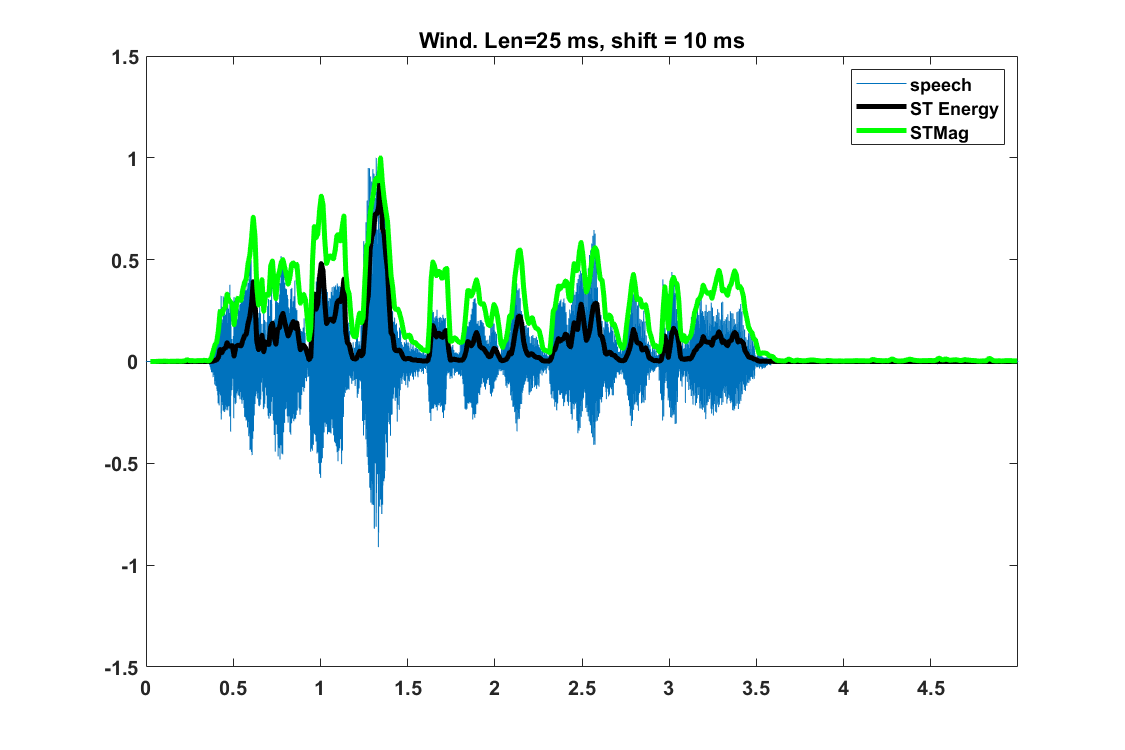

plot(t, speech);

hold on
T=WL_samp:WS_Samp:WL_samp+(length(STEn)-1)*WS_Samp;
T = T*(1/fs);
plot(T, STEn, 'k','LineWidth',3)
plot(T, STMag, 'g','LineWidth',3)
set(gca,'FontSize',12,'FontWeight','Bold')
title('Wind. Len=25 ms, shift = 10 ms')

axis tight
ylim([-1.5, 1.5])
legend('speech', 'ST Energy','STMag');

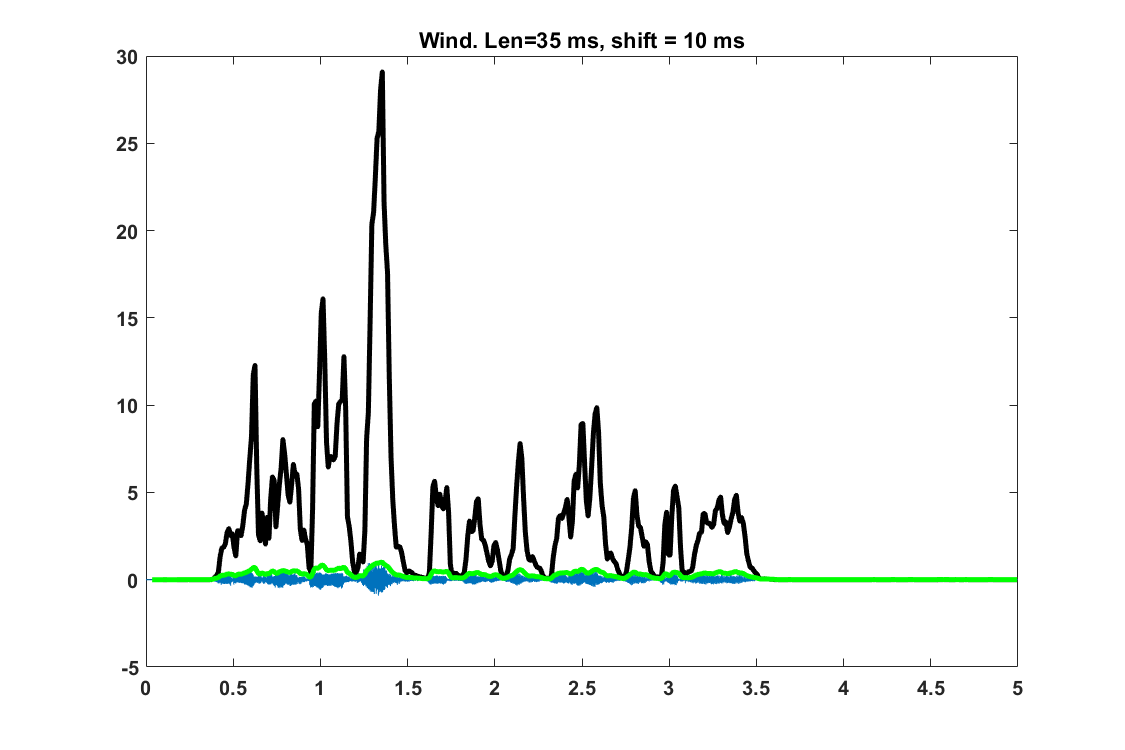

WL = 35;
WS = 10;

WL_samp = round(WL*0.001*fs);
WS_Samp = round(WS*0.001*fs);

[STEn, STMag] = STEn_STM_calc(speech, WL_samp, WS_Samp, fs);

STMag = STMag/max(STMag);
t= 0:(1/fs):(length(speech)-1)/fs;
figure('rend','painters','pos',[10 10 900 600]);
 
plot(t, speech);
 
hold on
T=WL_samp:WS_Samp:WL_samp+(length(STMag)-1)*WS_Samp;
T = T*(1/fs);
plot(T, STEn, 'k','LineWidth',3)
plot(T, STMag, 'g','LineWidth',3)
set(gca,'FontSize',12,'FontWeight','Bold')
title('Wind. Len=35 ms, shift = 10 ms')

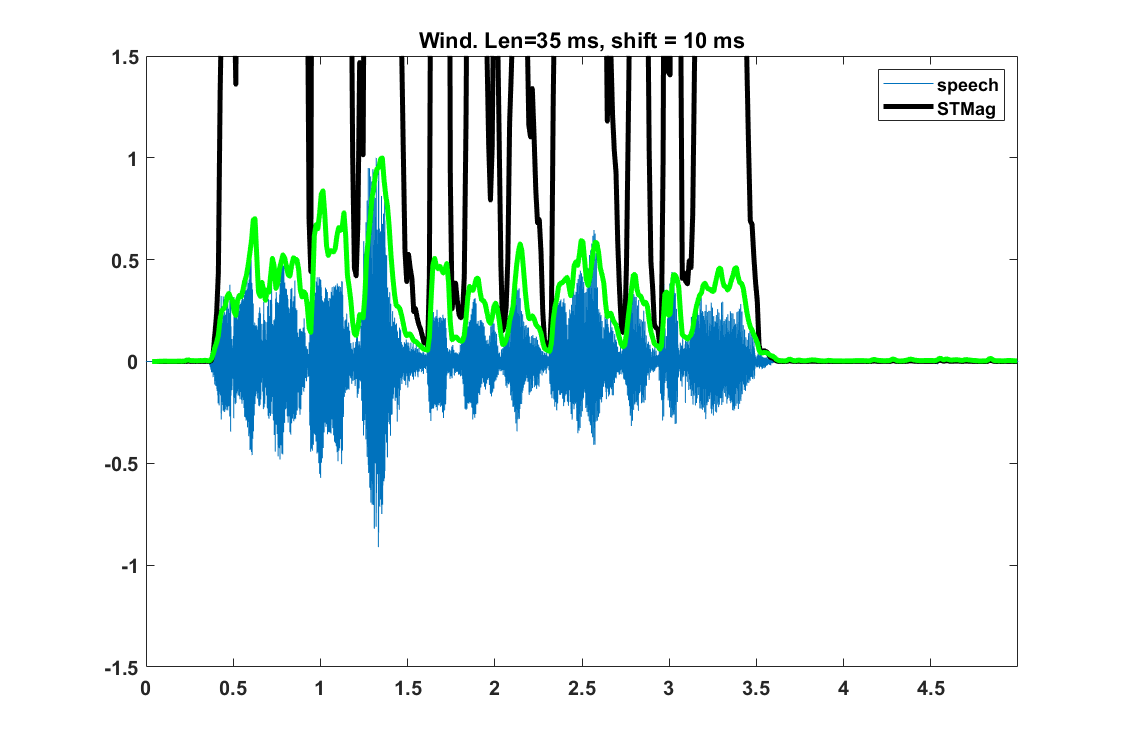

axis tight
ylim([-1.5, 1.5])
legend('speech', 'STMag');

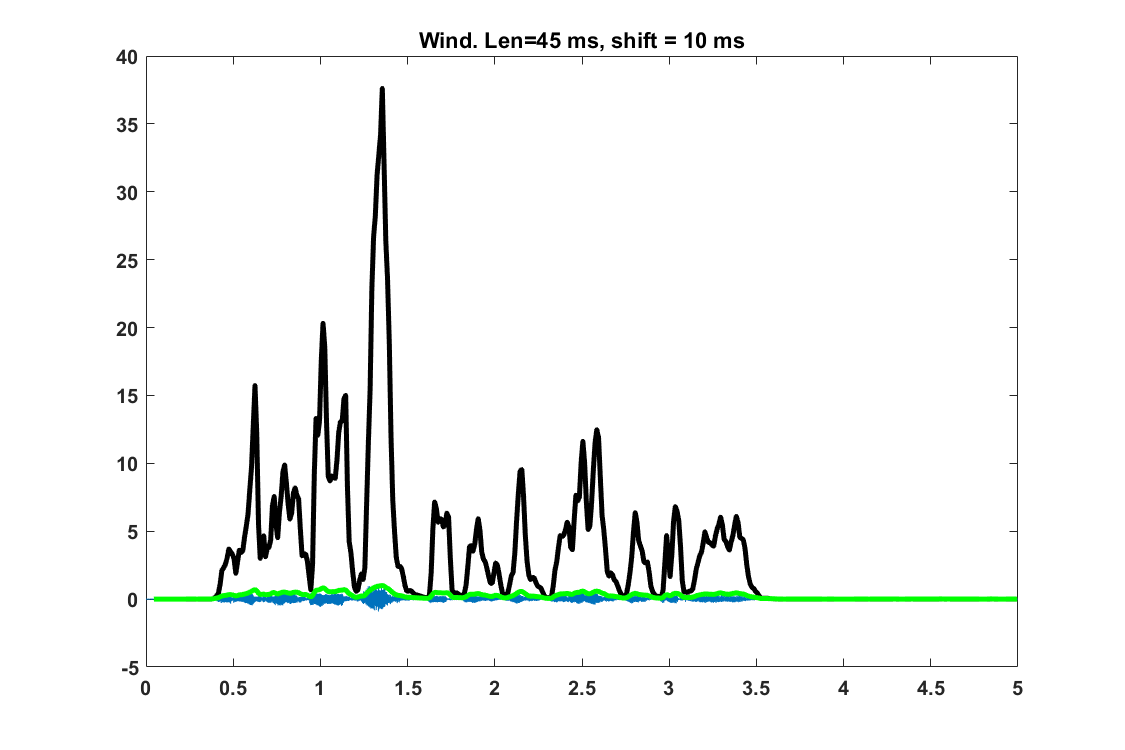

 
WL = 45;
WS = 10;


WL_samp = round(WL*0.001*fs);
WS_Samp = round(WS*0.001*fs);

[STEn, STMag] = STEn_STM_calc(speech, WL_samp, WS_Samp, fs);

STMag = STMag/max(STMag);
t= 0:(1/fs):(length(speech)-1)/fs;
figure('rend','painters','pos',[10 10 900 600]);

plot(t, speech);

hold on
T=WL_samp:WS_Samp:WL_samp+(length(STMag)-1)*WS_Samp;
T = T*(1/fs);
plot(T, STEn, 'k','LineWidth',3)
plot(T, STMag, 'g','LineWidth',3)
set(gca,'FontSize',12,'FontWeight','Bold')
title('Wind. Len=45 ms, shift = 10 ms')

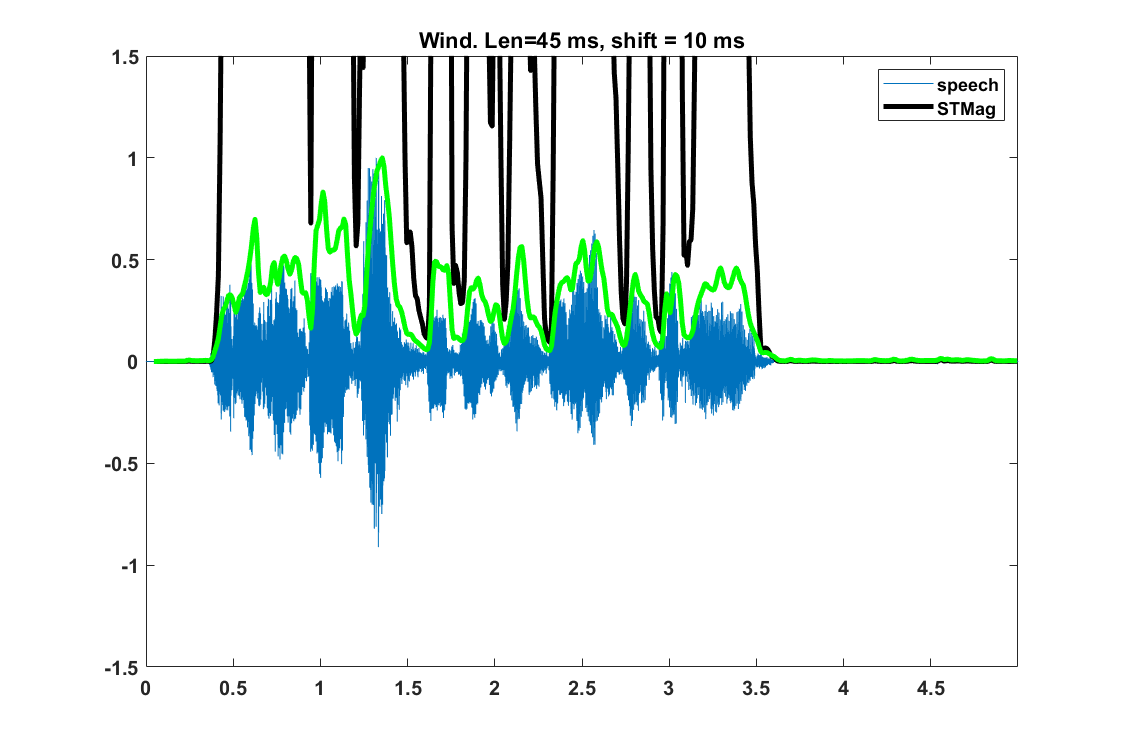

axis tight
ylim([-1.5, 1.5])
legend('speech', 'STMag');

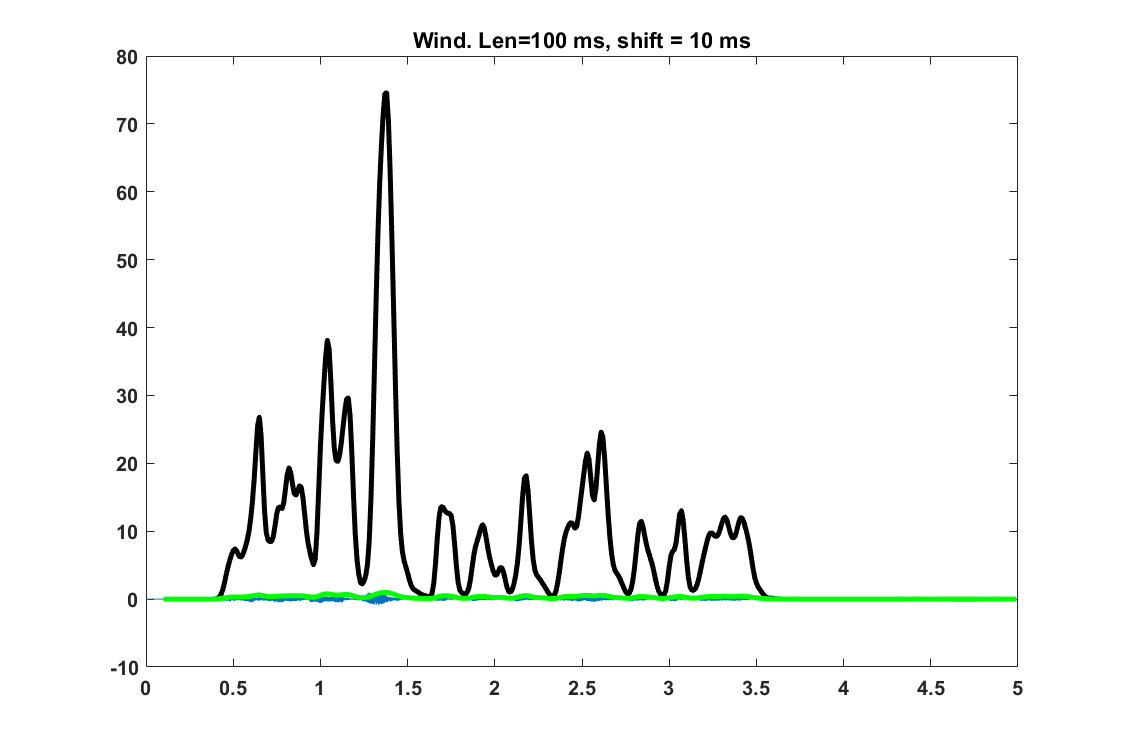


WL = 100;
WS = 10;

WL_samp = round(WL*0.001*fs);
WS_Samp = round(WS*0.001*fs);

[STEn, STMag] = STEn_STM_calc(speech, WL_samp, WS_Samp, fs);

STMag = STMag/max(STMag);
t= 0:(1/fs):(length(speech)-1)/fs;
figure('rend','painters','pos',[10 10 900 600]);

plot(t, speech);

hold on
T=WL_samp:WS_Samp:WL_samp+(length(STMag)-1)*WS_Samp;
T = T*(1/fs);
plot(T, STEn, 'k','LineWidth',3)
plot(T, STMag, 'g','LineWidth',3)
set(gca,'FontSize',12,'FontWeight','Bold')
title('Wind. Len=100 ms, shift = 10 ms')

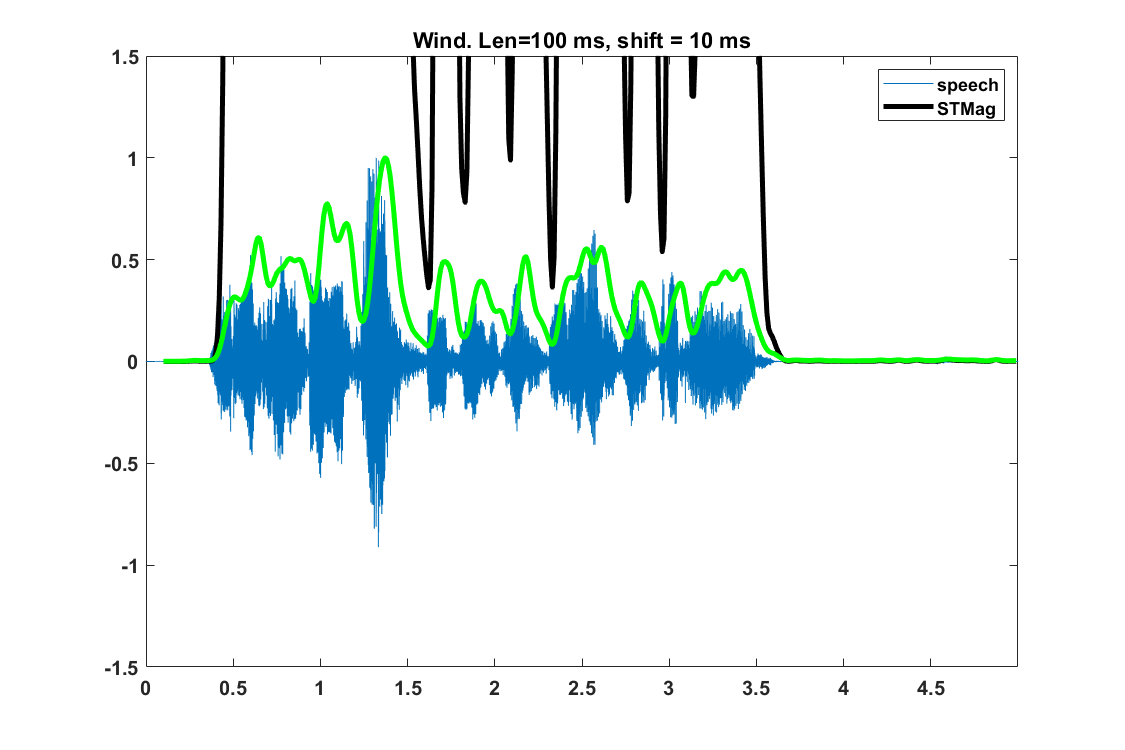

axis tight
ylim([-1.5, 1.5])
legend('speech', 'STMag');

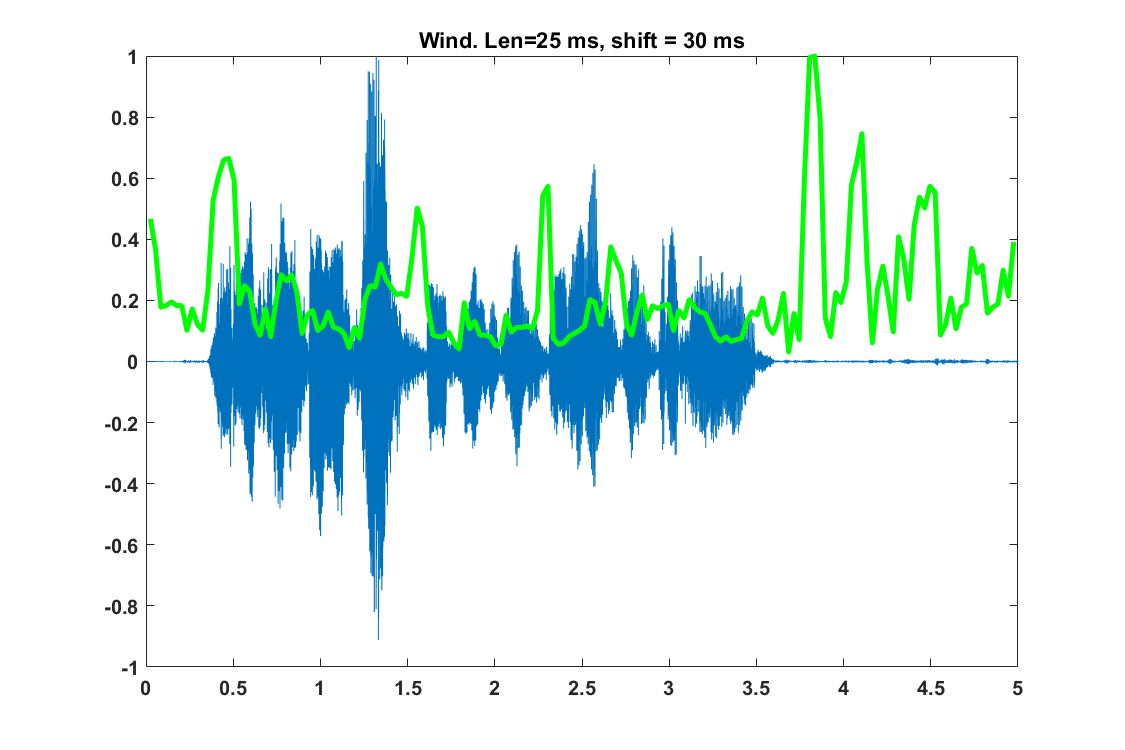


% ZCR calulation
WL = 25;
WS = 30;

WL_samp = round(WL*0.001*fs);
WS_Samp = round(WS*0.001*fs);

Num_frames = round(  (length(speech)-WL_samp)/WS_Samp );
ZCR = zeros(1,Num_frames);


for i=1:Num_frames
     startsamp = (i-1)*WS_Samp+1;
     EndSamp = startsamp+WL_samp-1;
     CurrSpeech  = speech(startsamp :EndSamp);
     CurrSpeechWin = (CurrSpeech).*hamming(WL_samp);
     sign_sig = sign(CurrSpeechWin);
     ZCR(i) = (1/(2*length(WL_samp))) * sum( ( abs (sign_sig(2:end)- sign_sig(1:end-1))));
    
 
end

ZCR = ZCR/max(ZCR);
t= 0:(1/fs):(length(speech)-1)/fs;
figure('rend','painters','pos',[10 10 900 600]);

plot(t, speech);    

hold on
T=WL_samp:WS_Samp:WL_samp+(length(ZCR)-1)*WS_Samp;
T = T*(1/fs);
plot(T, ZCR, 'g','LineWidth',3)
set(gca,'FontSize',12,'FontWeight','Bold')
title('Wind. Len=25 ms, shift = 30 ms')

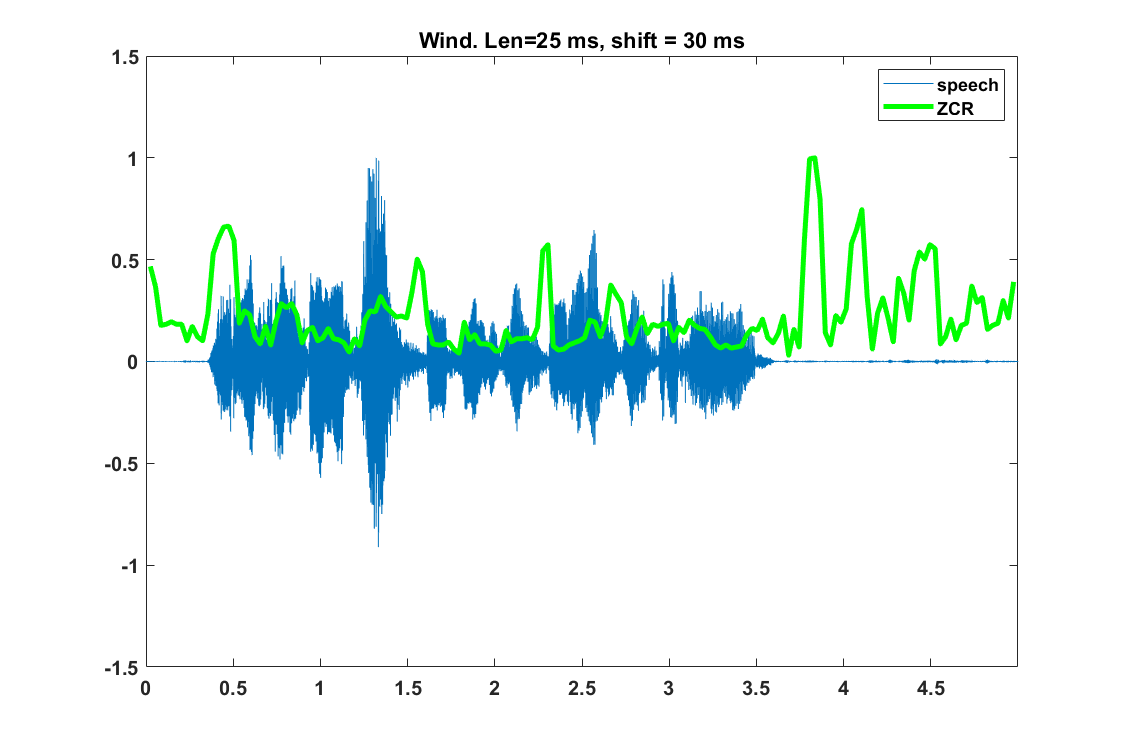

axis tight
ylim([-1.5, 1.5])
legend('speech', 'ZCR');

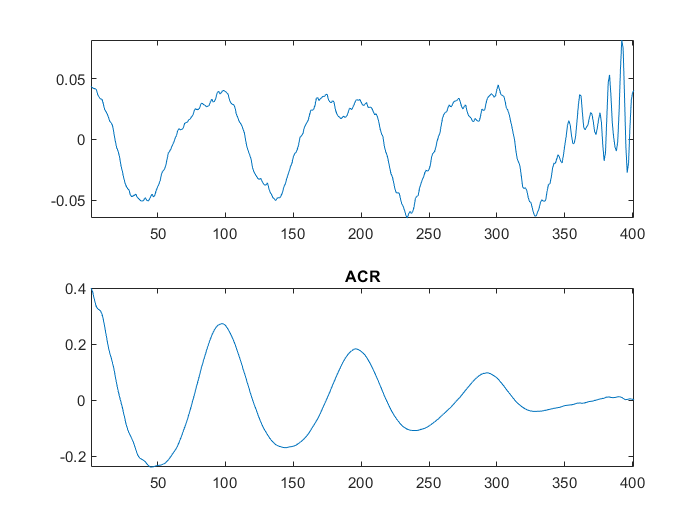


temp=1;

a_in_dark = 1.790; % in sec obtained from the plot

a_in_dark_sample = round(a_in_dark*fs);

half_wideband_windwolen = round(25*0.001*fs/2);
sig = speech(a_in_dark_sample-half_wideband_windwolen:a_in_dark_sample+half_wideband_windwolen);

% calulate the autocorrelation function
for speechInd=1:length(sig)
     speech_lagged = sig(speechInd:end);
     ACR_1(speechInd) = sum( sig(1:length(speech_lagged)).*speech_lagged);
end

figure;
subplot(2,1,1);plot(sig); 
axis tight
subplot(2,1,2);plot(ACR_1);title('Short-time utocorrelation function')
axis tight


title('ACR')

temp=1;